# **Calculation of elemental iso-concentration surfaces**

Note: the variable names here overwrite any variables of the same name in the workspace!

## Selection of atoms to to use for isoconcentration surface

Gather pos variable in decomposed form

posVariable = "pos"; % get variable from workspace
pos = eval(posVariable);

Select element for which the iso-surface is calculated for

elements = '{''C''}'; % get element for the isosuface
elements = eval(elements); % elements are parsed as cell arrays of char
allElements = categories(pos.atom); % all elements in the pos file

## Calculation of voxelisation

The voxelisation is a 3D histogram. In order to calculate a voxelisation, we need to determine the bin centers of the voxels. This can be done using the gridVectorFromPos function. For this, we need to specify the voxel size 'bin'

voxelSize = 3; % bin size of voxelisation
gridVectors = gridVectorFromPos(pos,voxelSize);

To obtain the concentration of each voxel, we calculate the count of atoms of the specified element and devided it by the count of all atoms in the voxel.

solVox = posToVoxel(pos,gridVectors,elements); % voxel count of element
vox = posToVoxel(pos,gridVectors,allElements); % voxel count of all elements

concentration = solVox./vox;
% conc(isnan(conc)) = 0; % set all elements that are not a number to 0.

We can plot a histogram of the individual voxel concentrations to get an idea what a good iso value would be

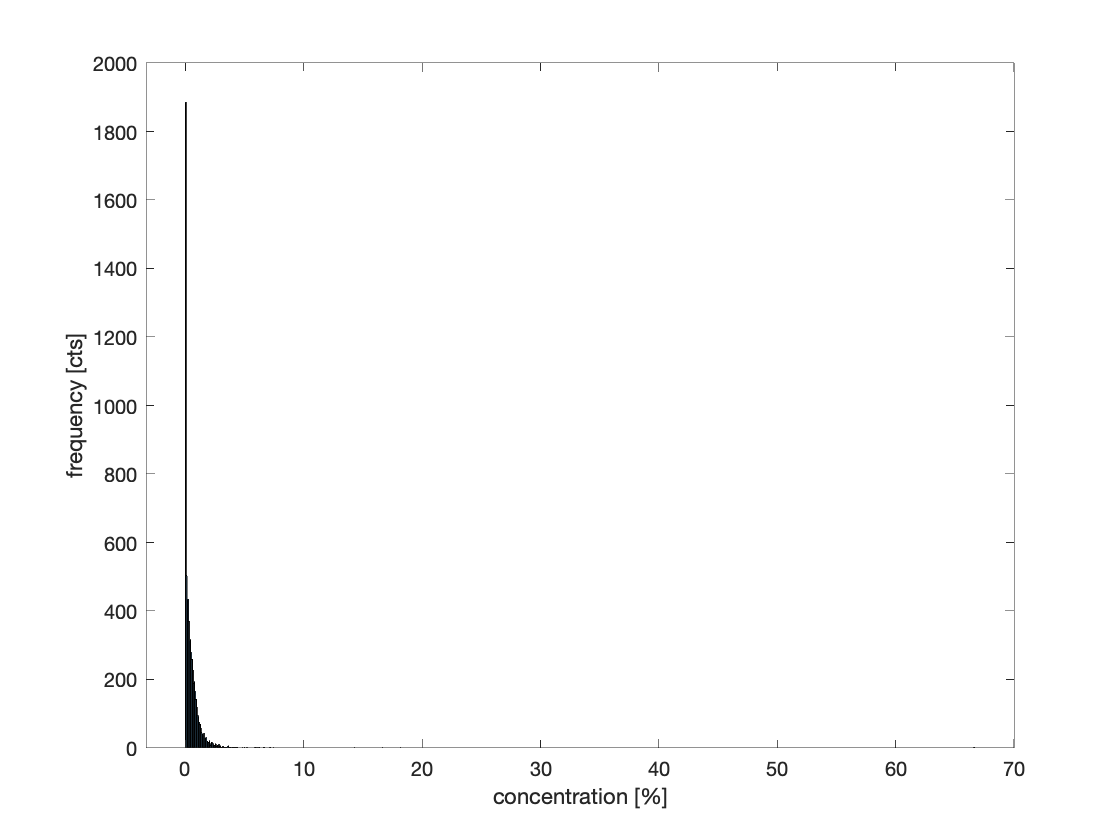

numberOfBins = 1000;
h = histogram(concentration(:)*100,numberOfBins); % concentration in %
h.Parent.XLabel.String = 'concentration [%]'; % set X Label
h.Parent.YLabel.String = 'frequency [cts]'; % set Y Label

## Calculation of isoconcentration surface

After choosing an iso-concentration value, the iso-concentration surface is calculated using the Marching Cubes algorithm (Lorensen and Cline ....)

The iso-surface is represented as a triangulated surface, consisting of vertices and trianges. Matlab calls these objects a 'patch'.

isoConcentrationValue = 0.7 / 100 % iso-concentration value in %

isoConcentrationValue = 0.0070


isoSurface = isosurface(gridVectors{2}, gridVectors{1}, gridVectors{3}, concentration,isoConcentrationValue); 
% the x and y grid vectors are swapped due to an inconsistancy in Matlabs way to calculate iso-surfaces

visualisation of the iso-surface

pax = axes(figure("Name",'iso-surface'));
p = patch(isoSurface); 
APTifyAxis; % adjusts axes colors and inverts the z axis
axis equal; 
rotate3d on;

Change color and other options of the display

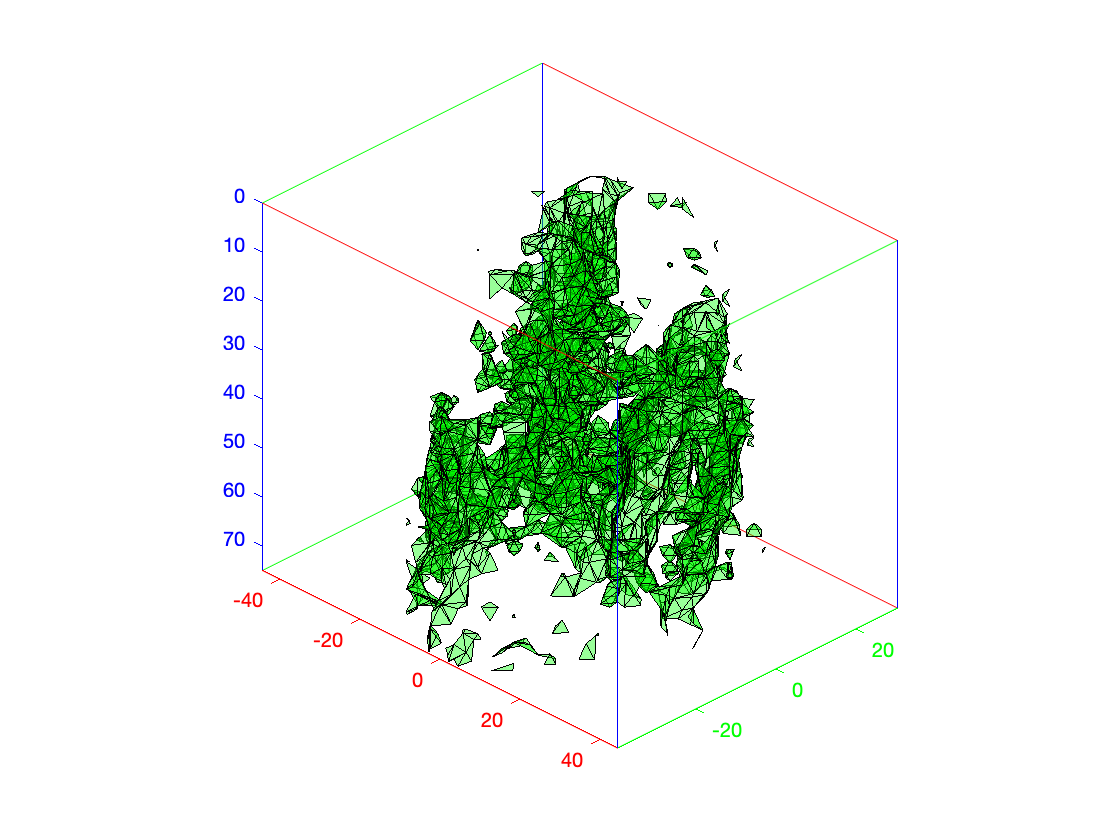

p.FaceColor = 'g';
faceAlpha = 0.4; % opacity level of surface in plot
p.FaceAlpha = faceAlpha;

view([45 30]); % adjust axis view direction

## **Isosurface data treatement**

### **Removal of small objects**

We can then remove all iso-surfaces that contain less than a set number of vertices

Nmin = 10

Nmin = 10

filteredIsosurface = filterPatchSize(isoSurface,Nmin);

visualize the filtered iso-surface

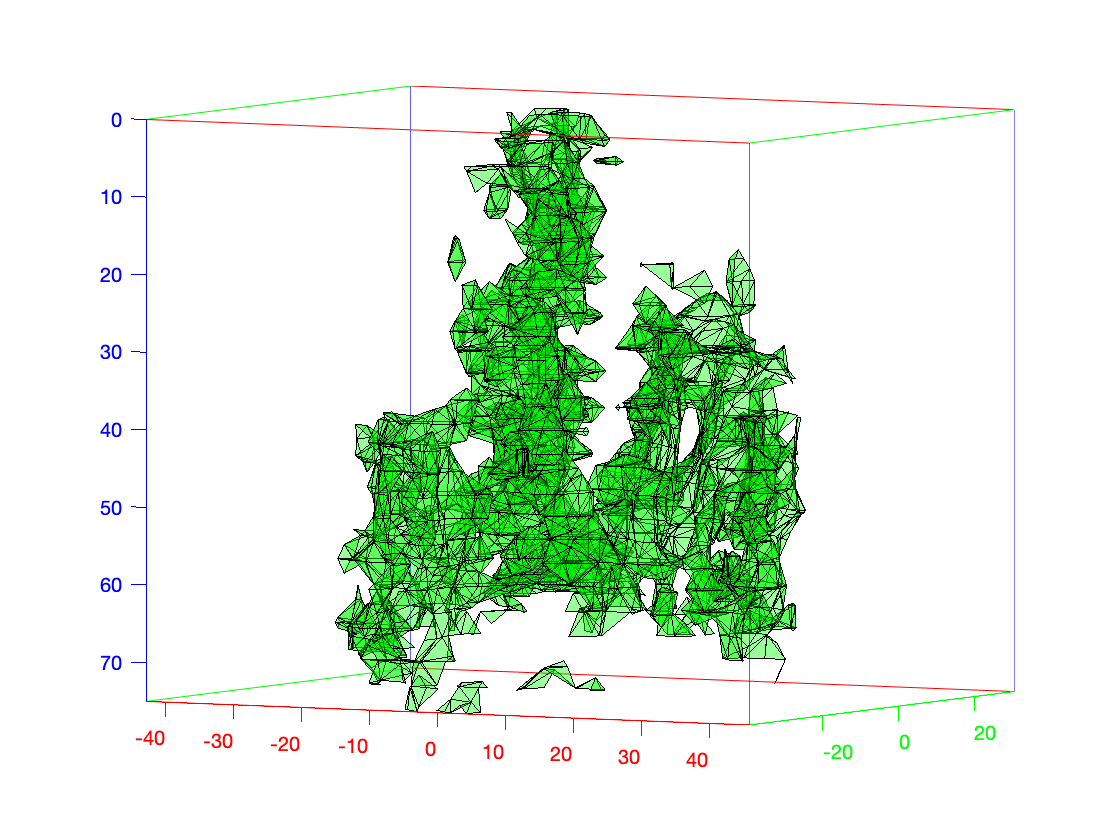

pax = axes(figure("Name",'iso-surface'));
p = patch(filteredIsosurface); 
APTifyAxis; % adjusts axes colors and inverts the z axis
axis equal; 
rotate3d on;
p.FaceColor = 'g';
p.FaceAlpha = faceAlpha;
view([45 30]); % adjust axis view direction

### Generation of individual objects from loose parts

We can split the iso-surface based on its connected parts, to focus our analysis on individual objects.

individualIsoSurfaces = splitFV(filteredIsosurface.faces,filteredIsosurface.vertices);
numObjects = length(individualIsoSurfaces) % number of individual iso surfaces

numObjects = 2

visualize the objects and set the colors to random

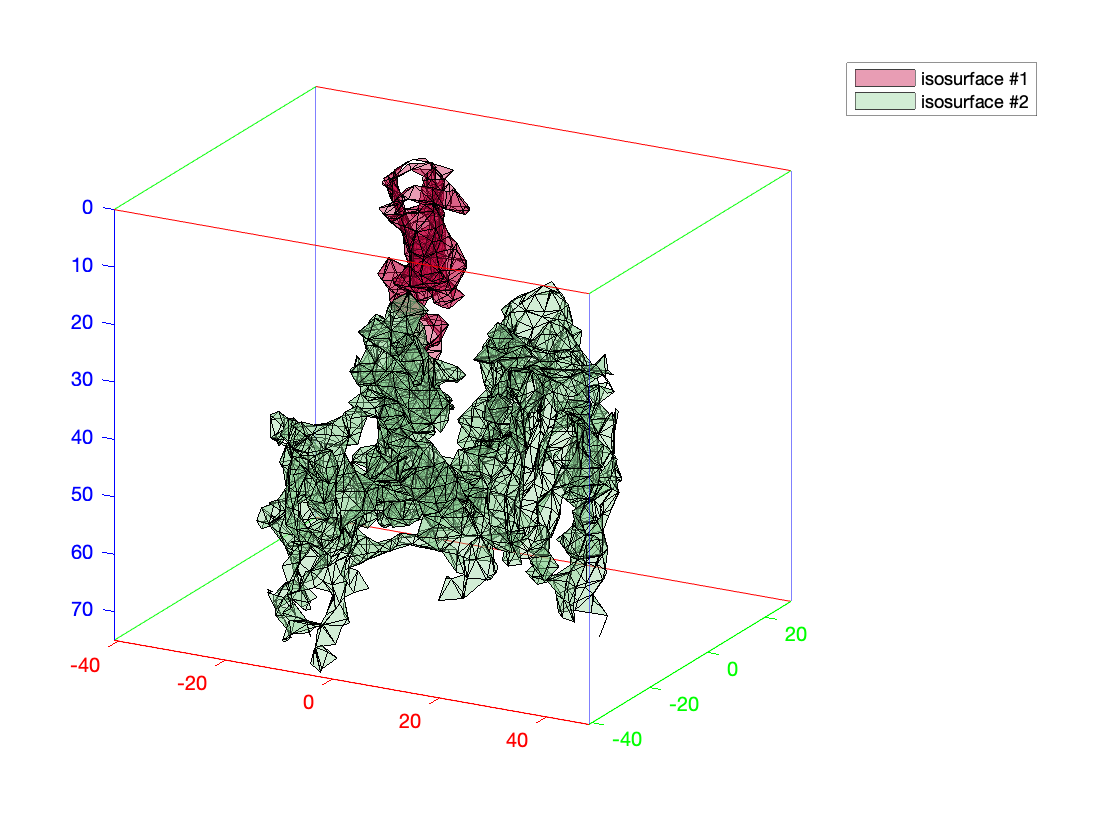

psax = axes(figure("Name",'individual iso-surfaces'));
colors = rand([numObjects, 3]);
for obj = 1:numObjects
    ph(obj) = patch(individualIsoSurfaces(obj));
    ph(obj).FaceColor = colors(obj,:);
    ph(obj).FaceAlpha = faceAlpha;
    ph(obj).DisplayName = ['isosurface #' num2str(obj)];
end
APTifyAxis; % adjusts axes colors and inverts the z axis
axis equal; 
legend('show','Location','northeastoutside')
rotate3d on;
view([45 30]); % adjust axis view direction